opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["m", "f", "e"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable("C:\Users\maxdesktop\MATLAB Drive\Lab Week 13\Question_5\data.csv", opts);
m = tbl.m;
f = tbl.f;
e = tbl.e;
clear opts tbl;


t = m * .0001 * 9.81;

clf;

g = errorbar(t, f, e, e);
g.LineStyle = 'none';
hold on

%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( t, f );

% Set up fittype and options.
ft = fittype( 'poly1' )

ft =      Linear model Poly1:
     ft(p1,p2,x) = p1*x + p2


% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft )

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       212.2  (181.2, 243.2)
       p2 =       57.48  (45.64, 69.32)

gof = struct with fields:
           sse: 20.0103
       rsquare: 0.9937
           dfe: 3
    adjrsquare: 0.9916
          rmse: 2.5827


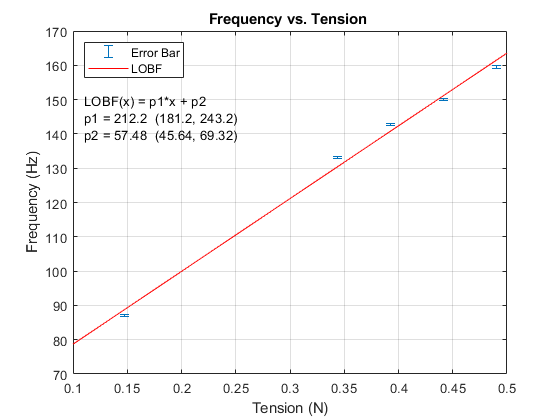



% Plot fit with data.
plot( fitresult );
legend('Error Bar', 'LOBF', 'Location', 'NorthWest', 'Interpreter', 'none' );
% Label axes
xlabel( 'Tension (N)');
ylabel( 'Frequency (Hz)');
title('Frequency vs. Tension ')

text(.11, 145, string("LOBF(x) = p1*x + p2" + newline + ...
    "p1 = 212.2  (181.2, 243.2)" + newline + ...
    "p2 = 57.48  (45.64, 69.32)"));
grid on